# PRÁCTICA 2 - RECONOCIMIENTO AUTOMÁTICO DE DÍGITOS MANUSCRITOS

## Data

###     Data loading

% Data parameters
imgFile = "train-images-idx3-ubyte";
labelFile = "train-labels-idx1-ubyte";
readDigits = 1000;
offset = 0;

[imgs labels] = readMNIST(imgFile, labelFile, readDigits, offset);

% Setting random numbers seed
rng(0, 'twister'); 

###     Features vectors generation & data set construction

featuresVectorsOfImgs = [];

% Features vectors generation
for i = 1:readDigits
    fv = featuresVector(imgs(:, :, i));
    featuresVectorsOfImgs = [featuresVectorsOfImgs ; array2table(fv)];
end

% Labeling
% Poner label a todas las columnas ?
featuresVectorsOfImgs.Labels = labels;


###     Split of set in training set (80%) and test set


% Trainin data: 80% ; Test data: 20%
p = cvpartition(readDigits, "HoldOut", 0.2);
i = p.test;

% Splitting data
trainingData = featuresVectorsOfImgs(~i, :);
testData = featuresVectorsOfImgs(i, :);

## Training and Testing ML Models

###     Parameters and CV preparation

% Parameters
k = 10;     % k of K-Fold CV

trainingData.Labels

ans =      5
     0
     4
     9
     2
     1
     3
     1
     4
     3


% CV split of training data
cvp = cvpartition(trainingData.Labels, 'KFold', k); % Peta estrepitosamente


###     Decision Tree

X_train = trainingData(:, 1:end-1);
Y_train = trainingData(:, end);


t = Fit template for classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: ''
               KernelScale: []
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: 1
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


% Training con CV (cvp)
t = fitctree(X_train, Y_train); 

genError = 0.1613


% Extracción información del trainign


error = 0.0375

% Predicciones en test

% Extracción de información en test


% Ejemplos ricos: https://es.mathworks.com/help/stats/examples/classification.html


% Exported models: quadraticSVM
quadraticSVM.HowToPredict

ans =     'To make predictions on a new table, T, use: 
       yfit = c.predictFcn(T) 
     replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. 
      
     The table, T, must contain the variables returned by: 
       c.RequiredVariables 
     Variable formats (e.g. matrix/vector, datatype) must match the original training data. 
     Additional variables are ignored. 
      
     For more information, see How to predict using an exported model.'


quadraticSVM.RequiredVariables

ans = 1×40 cell array
    {'fv1'}    {'fv10'}    {'fv11'}    {'fv12'}    {'fv13'}    {'fv14'}    {'fv15'}    {'fv16'}    {'fv17'}    {'fv18'}    {'fv19'}    {'fv2'}    {'fv20'}    {'fv21'}    {'fv22'}    {'fv23'}    {'fv24'}    {'fv25'}    {'fv26'}    {'fv27'}    {'fv28'}    {'fv29'}    {'fv3'}    {'fv30'}    {'fv31'}    {'fv32'}    {'fv33'}    {'fv34'}    {'fv35'}    {'fv36'}    {'fv37'}    {'fv38'}    {'fv39'}    {'fv4'}    {'fv40'}    {'fv5'}    {'fv6'}    {'fv7'}    {'fv8'}    {'fv9'}


confussionTrain =   ConfusionMatrixChart with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 double]

  Show all properties


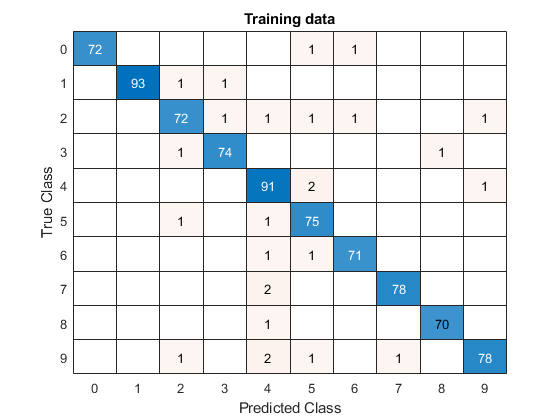


% Extracción información del training
y_train = quadraticSVM.predictFcn(trainingData);
figure, confussionTrain = confusionchart(trainingData.Labels,y_train), title('Training data');

confussionTest =   ConfusionMatrixChart with properties:

    NormalizedValues: [10×10 double]
         ClassLabels: [10×1 double]

  Show all properties


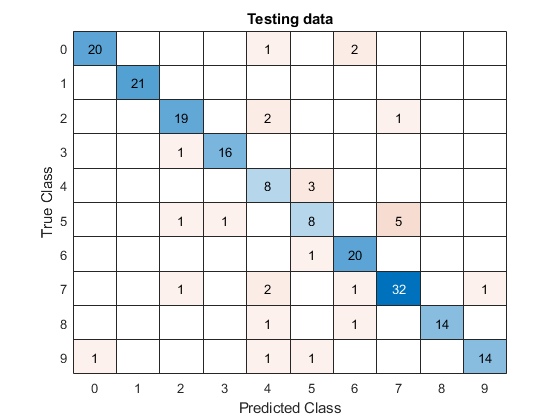


% Predicciones en test
y_test = quadraticSVM.predictFcn(testData);

% Extracción de información en test
figure, confussionTest = confusionchart(testData.Labels,y_test), title('Testing data');


% METRICS
% Confusion matrix
[confMat,order] = confusionmat(testData.Labels,y_test);

% Recall
for i =1:size(confMat,1)
    recall(i)=confMat(i,i)/sum(confMat(:,i));
end
recall(isnan(recall))=[];

Recall = sum(recall)/size(confMat,1)

Recall = 0.8515


% Precision
for i =1:size(confMat,1)
    precision(i)=confMat(i,i)/sum(confMat(i,:));
end
Precision = sum(precision)/size(confMat,1)

Precision = 0.8451


% F-score
F_score=2*Recall*Precision/(Precision+Recall)

F_score = 0.8483

## Functions

###     Features vector generation function

function features = featuresVector(img)
    img = imresize(img, [40, 40]);      %????
    img = im2bw(img, graythresh(img));
    
    features = [];

    % Concavities
    cf = concavitiesFeatures(img);
    features = [features cf];
    
    % Holes
    hf = holesFeatures(img);
    features = [features hf];
    
    % Convex Hull
    chf = convexHullFeatures(img);
    features = [features chf];
end

###     Feature extraction functions (finally used)

####         Concavities

            The extracted concavities features are (for each concavity): centroid_x, centroid_y, area, major_axis_lenght,

            minor_axis_lenght. 

function cf = concavitiesFeatures(img)
    imgWithoutHoles = imfill(img, 'holes');
    
    ch = bwconvhull(imgWithoutHoles, 'objects');
    
    concavities = ch-imgWithoutHoles;
    
    [eti num] = bwlabel(concavities,4);
    
    Dades = regionprops(eti,'all');
    
    N = 5;
    if size(Dades, 1) > 1
        T = struct2table(Dades);
        toDelete = T.Area < 4;
        T(toDelete,:) = [];
        sortedT = sortrows(T, 'Centroid', "descend");
        Dades = table2struct(sortedT);
        Dades = Dades(1:min(size(Dades, 1), N));
    end
    
    centroidsX = zeros(1, N);
    centroidsY = zeros(1, N);
    area = zeros(1, N);
    majorAxisLength = zeros(1, N);
    minorAxisLength = zeros(1, N);
    
    for i=1:size(Dades, 1)
        dada = Dades(i);
        centroidsX(1, i) = dada.Centroid(1);
        centroidsY(1, i) = dada.Centroid(2);
        area(1, i) = dada.Area;
        majorAxisLength(1, i) = dada.MajorAxisLength;
        minorAxisLength(1, i) = dada.MinorAxisLength;
    end
    
    cf = [centroidsX centroidsY area majorAxisLength minorAxisLength];
end


####         Holes

            The extracted holes features are (for each hole): centroid_x, centroid_y, area, major_axis_lenght,

            minor_axis_lenght. 

function hf = holesFeatures(img)
    imgWithoutHoles = imfill(img, 'holes');
    
    holes = imgWithoutHoles-img;

    [eti, num] = bwlabel(holes,4);
    
    Dades = regionprops(eti,'all');
        
    N = 2;
    if size(Dades, 1) > 1
        T = struct2table(Dades);
        toDelete = T.Area < 4;
        T(toDelete,:) = [];
        sortedT = sortrows(T, 'Centroid', "descend");
        Dades = table2struct(sortedT);
        Dades = Dades(1:min(size(Dades, 1), N));
    end
    
    centroidsX = zeros(1, N);
    centroidsY = zeros(1, N);
    area = zeros(1, N);
    majorAxisLength = zeros(1, N);
    minorAxisLength = zeros(1, N);
    
    for i=1:size(Dades, 1)
        dada = Dades(i);
        centroidsX(1, i) = dada.Centroid(1);
        centroidsY(1, i) = dada.Centroid(2);
        area(1, i) = dada.Area;
        majorAxisLength(1, i) = dada.MajorAxisLength;
        minorAxisLength(1, i) = dada.MinorAxisLength;
    end
    
    hf = [centroidsX centroidsY area majorAxisLength minorAxisLength];
end


####         Convex hull

            The extracted holes features are: centroid_x, centroid_y, area, major_axis_lenght,

            minor_axis_lenght. 

function chf = convexHullFeatures(img)
    ch = bwconvhull(img, 'objects');
    
    [eti num] = bwlabel(ch,4);
    
    dada = regionprops(eti,'all');
    
    % si s'extrau més d'un objecte que agafi el més gran
    % ja que serà aquell que representi la convex hull
    if size(dada, 1) > 1
        T = struct2table(dada);
        sortedT = sortrows(T, 'Area', "descend");
        dada = table2struct(sortedT);
        dada = dada(1);
    end
    
    centroidsX = dada.Centroid(1);
    centroidsY = dada.Centroid(2);
    area = dada.Area;
    majorAxisLength = dada.MajorAxisLength;
    minorAxisLength = dada.MinorAxisLength;
    
    chf = [centroidsX centroidsY area majorAxisLength minorAxisLength];
end